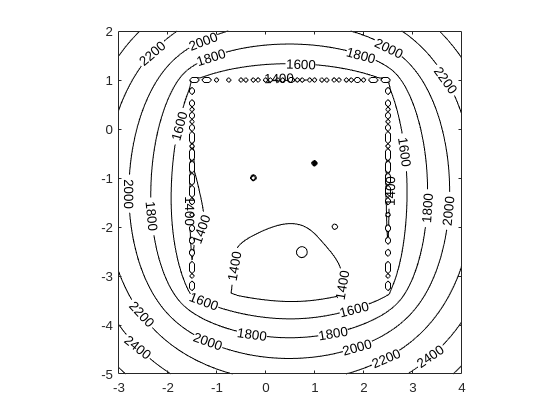

[x,y]=meshgrid(-3:0.05:4,-5:0.05:2);

barrel = log(sqrt((x-0.75).^2+(y+2.5).^2));

box_1 = log(sqrt((x-1.41).^2+(y+2).^2));
box_2 = log(sqrt((x-1).^2+(y+0.7).^2));
box_3 = log(sqrt((x+0.25).^2+(y+1).^2));

% Left Wall
left_wall = 0;

for a = -1.5:0.01:2.5
    left_wall = left_wall - log(sqrt((x-a).^2 + (y+3.37).^2));
end

% Right Wall
right_wall = 0;

for a = -1.5:0.01:2.5
    right_wall = right_wall - log(sqrt((x-a).^2 + (y-1).^2));
end

% Top Wall
top_wall = 0;

for a = -3.37:0.01:1
    top_wall = top_wall - log(sqrt((x+1.5).^2 + (y-a).^2));
end

% Bottom Wall
bottom_wall = 0;

for a = -3.37:0.01:1
    bottom_wall = bottom_wall - log(sqrt((x-2.5).^2 + (y-a).^2));
end

%v = barrel - box_1 - box_2 - box_3 - left_wall - right_wall - top_wall - bottom_wall
v = 100*barrel - 70*box_1 - 40*box_2 - 50*box_3 - left_wall - right_wall - top_wall - bottom_wall;

contour(x,y,v,'k','ShowText','On')
axis equal